clear all;

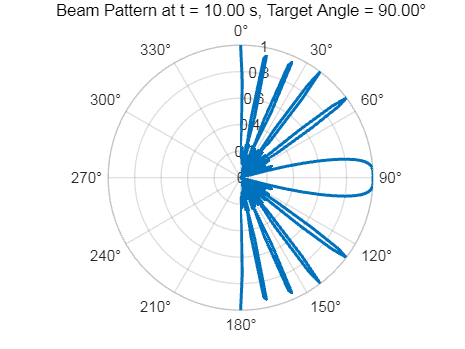

% Radar Toolbox Implementation
% 参数设置
c = physconst('LightSpeed'); % 光速
f = 5e9;                    % 雷达初始频率 (Hz)
d_min = 0.3;                % 最小阵元间距 (m)
d_max = 10;                 % 最大阵元间距 (m)
d = d_min;                  % 初始阵元间距 (m)
lambda = 2 * d;             % 波长，满足 d = lambda / 2

% 固定5x5阵列参数
num_rows = 5;
num_cols = 5;
num_drones = num_rows * num_cols; % 总阵元数量

% 无人机阵列位置
x_positions = repmat((0:num_cols-1) * d, 1, num_rows); % X轴位置
y_positions = reshape(repmat((0:num_rows-1)' * d, 1, num_cols)', 1, []); % Y轴位置
z_positions = zeros(1, num_drones); % Z轴固定在0

% 阵元位置矩阵
element_positions = [x_positions; y_positions; z_positions];

% 仿真参数
simulation_time = 10;       % 仿真时间 (秒)
time_step = 0.1;            % 时间步长 (秒)
theta_scan = 0:1:180;       % 扫描角度范围 (°)
time = 0:time_step:simulation_time;

% 初始化变量
array_factors = zeros(length(time), length(theta_scan)); % 存储每个时刻的阵列因子
detected_targets = zeros(1, length(time)); % 存储检测到的目标方向

% 固定阵列相控阵雷达
fixed_array = phased.URA('Size', [num_rows num_cols], 'ElementSpacing', [d d]); % 5x5固定阵列

% 模拟动态目标方向
theta_target = 60 * sin(2 * pi * 0.1 * time) + 90; % 动态目标方向随时间变化

% 波束扫描仿真
for t = 1:length(time)
    % 计算波束方向增益
    sv = phased.SteeringVector('SensorArray', fixed_array, 'PropagationSpeed', c);
    for i = 1:length(theta_scan)
        % 使用导向矢量直接计算波束增益
        weights = sv(f, theta_scan(i)); % 导向矢量
        array_factors(t, i) = abs(sum(weights)); % 合成波束增益
    end

    % 归一化
    if max(array_factors(t, :)) > 0
        array_factors(t, :) = array_factors(t, :) / max(array_factors(t, :));
    end

    % 检测目标方向（只检测前半圆）
    [~, max_idx] = max(array_factors(t, :));
    detected_targets(t) = theta_scan(max_idx);
end

% 动态波束方向图动画
figure;
polarplot_handle = polarplot(deg2rad(theta_scan), array_factors(1, :), 'LineWidth', 2);
title('Dynamic Beam Pattern of Fixed 5x5 Array');
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.ThetaDir = 'clockwise';

for t = 1:length(time)
    polarplot_handle.ThetaData = deg2rad(theta_scan);
    polarplot_handle.RData = array_factors(t, :);
    title(sprintf('Beam Pattern at t = %.2f s, Target Angle = %.2f°', time(t), theta_target(t))); % 更新标题
    drawnow; % 强制刷新动画
    pause(0.05);
end

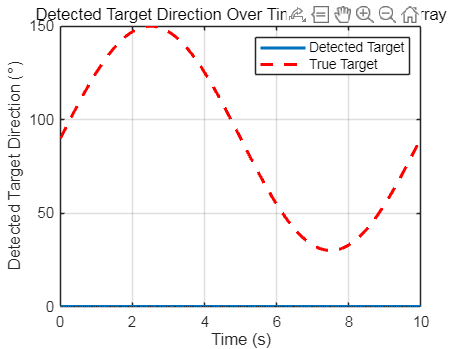


% 绘制检测到的目标方向随时间变化
figure;
plot(time, detected_targets, 'LineWidth', 2);
hold on;
plot(time, theta_target, 'r--', 'LineWidth', 2); % 添加真实目标方向
xlabel('Time (s)');
ylabel('Detected Target Direction (°)');
title('Detected Target Direction Over Time for Fixed 5x5 Array');
legend('Detected Target', 'True Target');
grid on;